## Eliminación de ruido mediante procesamiento en dominio de Fourier

Lectura de imagen con ruido

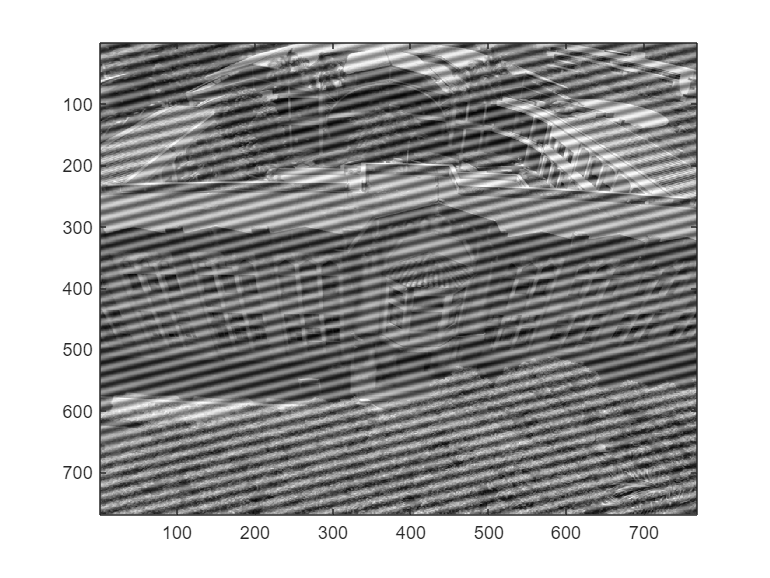

imagenConRuido = imread("b.png");
imagesc(imagenConRuido)
colormap("gray")

Se puede observar que en el dominio de fourier hay dos picos muy caracteristicos

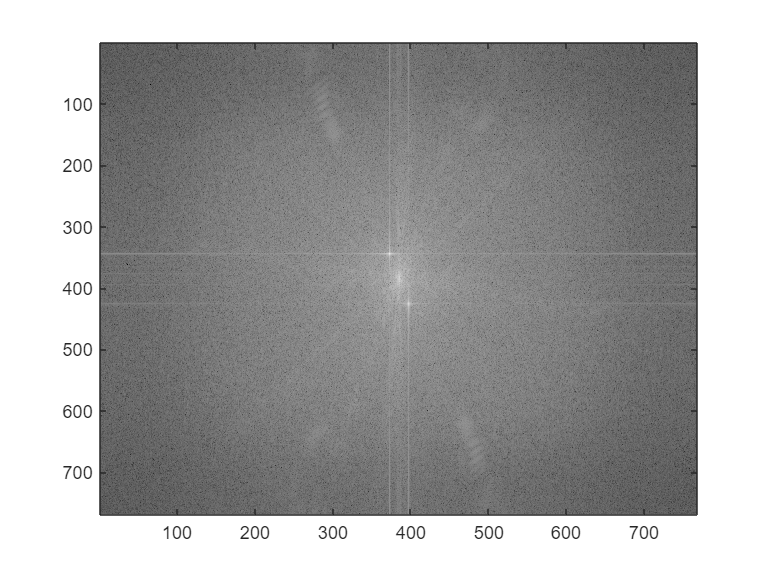

FFTimRuido = (fftshift(fft2(imagenConRuido)));
imagesc(log10(abs(FFTimRuido)))

Se encuentran las posisiones de los máximos ignorando el máximo central

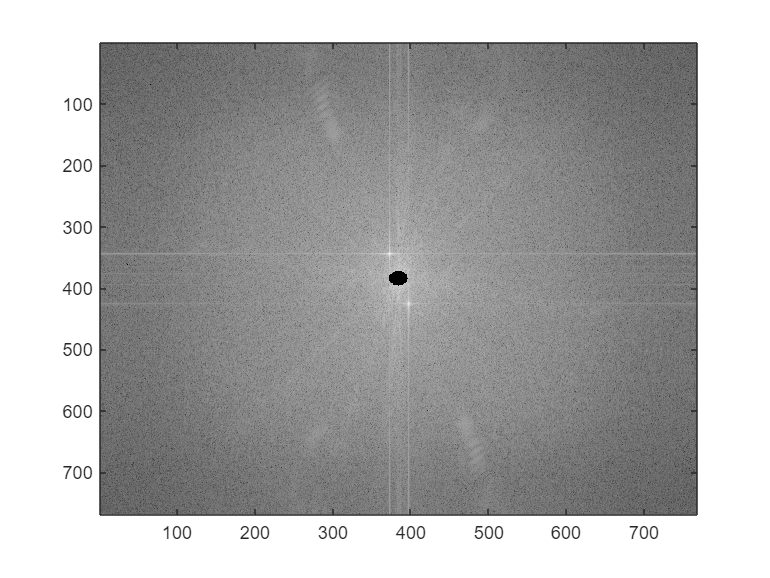

% A la fft de la imagen con ruido le aplicamos un filtro circular
% para quitarle el centro y poder buscar los maximos fuera del centro
FFTimRuidoSinCentro = FFTimRuido.*(~filtroCircular([768/2 768/2],12,size(FFTimRuido)));
imagesc(log10(abs(FFTimRuidoSinCentro)))

Se encuentran los maximos

[maximosY,maximosX] = find(abs(FFTimRuidoSinCentro) == max(abs(FFTimRuidoSinCentro),[],"all"))

maximosY =    344
   426


maximosX =    373
   397


% Se ponen las posiciones de los maximos en el siguiente array
centros = [[maximosX(1) maximosY(1)];[maximosX(2) maximosY(2)]];

Se utiliza la funcion de filtros circulares (filtroCircular.m) para crear un "obstaculo" en esas frecuencias especificas y que estas no pasen y por ende no se vean reflejadas en la imagen

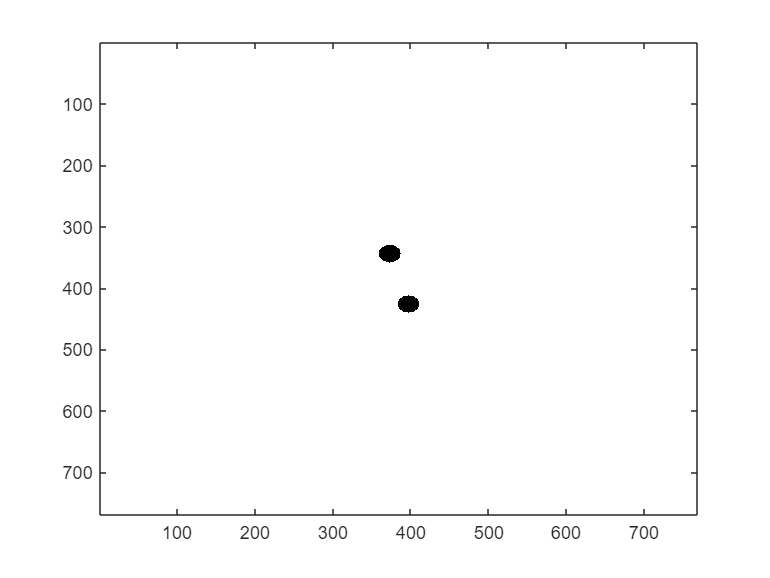

% Este filtro se colocaria en el plano de fourier
radio = 14;
filtro = double(~filtroCircular(centros,[radio;radio],[768 768]));
imagesc(filtro)

Hacemos pasar la imagen ruidosa por el montaje óptico colocando el anterior filtro en el plano de fourier

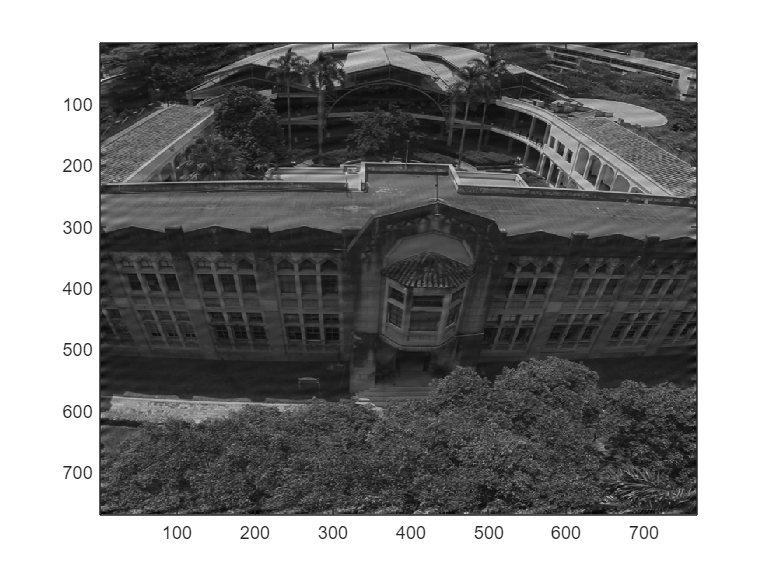

[imagenDeSalidaPura, imagenObservacion] = sistema4f(imagenConRuido,filtro);

% La imagen sale invertida por lo que se hace una rotacion de 180°
imagesc(imrotate(imagenObservacion,180))